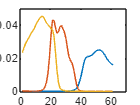

% 1.1

load("Ad.mat");
load("Ad2.mat");

plot(Ad);

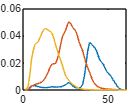

figure
plot(Ad2);


% Ad has more overlap --> shifts in color
% Double peaks, maybe lack some information in color depth
% Ad2 has more separation and better peaks, resulting in a more "accurate"
% picture

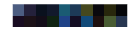

% 1.2

load("chips20.mat");
load("illum.mat");

% .* = Element-wise multiplication
% ' = Transpose
% d = Ad^t * e^t //t = transpose
d = Ad'*(chips20(:,:).*CIED65)';
d2 = Ad2'*(chips20(:,:).*CIED65)';

showRGB(d');

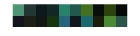

showRGB(d2');


% Ad has better dark green (Wave form more to left)
% Ad2 has brighter colors, more saturation and vibrant, Ad is more dark

% 2.1

e = ones(1,61);

Norm_Ad = Ad'*e';
Norm_Ad2 = Ad2'*e';

% The lower peaks will divide with a smaller number, resulting in a larger
% peak, meanwhile the high peaks will not grow as much

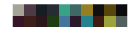

% 2.2 

RGB_D65_Calibrated_Ad = (Ad'*(chips20(:,:).*CIED65)')./Norm_Ad;
RGB_D65_Calibrated_Ad2 = (Ad2'*(chips20(:,:).*CIED65)')./Norm_Ad2;

showRGB(RGB_D65_Calibrated_Ad');

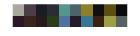

showRGB(RGB_D65_Calibrated_Ad2');

% Its alot different. The colors are more accurate and same.
% We can still see some flaws in the green colors, and some in the red, but
% its alot better

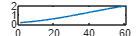

% 2.3

plot(CIEA) % Outdoor

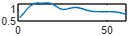

plot(CIED65) % Indoor

% We see that the intensity is larger outdoor
% More warm light from outdoor but "Constant"
% Indoor can see wave peaks more clear

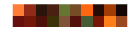

% 2.4 

RGB_CIEA_Calibrated_Ad = (Ad'*(chips20(:,:).*CIEA)')./Norm_Ad;

showRGB(RGB_CIEA_Calibrated_Ad') % Outdoor same light

showRGB(RGB_D65_Calibrated_Ad') % Indoor same light

% If we not adjust for the strong red in outdoor, the colors will be more
% red, same for indoor where blue is more strong

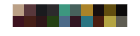

% 2.5
load("Ad.mat");
load('chips20.mat')
load('illum.mat')
R = ones(1,61);

Calibrated_CIEA = Ad'*(R.*CIEA)';
RGB_RAW_CIEA = Ad'*(chips20(:,:).*CIEA)'./Calibrated_CIEA;

Calibrated_D65 = Ad'*(R.*CIED65)';
RGB_RAW_D65 = Ad'*(chips20(:,:).*CIED65)'./Calibrated_D65;

showRGB(RGB_RAW_CIEA') % Outdoor

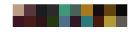

showRGB(RGB_RAW_D65')  % Indoor

% 3.1

load("xyz.mat")
load("Ad.mat");
load('chips20.mat')
load('illum.mat')

% White between 0-, Lec 1 slide 28 formula
Norm_factor = 100./(CIED65*xyz(:,2));

XYZ_D65_Ref = xyz'*(CIED65 .* chips20)'*Norm_factor;

% 3.2 

load("M_XYZ2RGB.mat");

% Convert RGB to XYZ

XYZ = inv(M_XYZ2RGB) * RGB_D65_Calibrated_Ad;

% XYZ to CIELAB 
% L = lightness 0-100, A = Green-red -128-127, B = Blue-yellow -128-127
[L, A, B] = xyz2lab(XYZ(1,:)', XYZ(2,:)', XYZ(3,:)');

% Storing values
C_LAB = zeros(3,20);
C_LAB(1,:) = L;
C_LAB(2,:) = A;
C_LAB(3,:) = B;

% Convert reference XYZ to CIELAB
[L, A, B] = xyz2lab(XYZ_D65_Ref(1,:)', XYZ_D65_Ref(2,:)', XYZ_D65_Ref(3,:)');

% Storing values
REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = A;
REF_LAB(3,:) = B;

% Compute color differences (ΔEab), slide 38
dE = sqrt((C_LAB(1,:)-REF_LAB(1,:)).^2+(C_LAB(2,:)-REF_LAB(2,:)).^2+(C_LAB(3,:)-REF_LAB(3,:)).^2);

% Calculate mean and max value
dE_mean = mean(dE)

dE_mean = 12.6418

dE_max = max(dE)

dE_max = 31.6232


% High mean, unacceptable due to very noticeable colorshifts
% On average the color deviate from reference color by a distance of 12.6
% in CIELAB color space
% Largest single color difference is 31.6, extremely high.

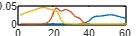

% 3.3

plot(Ad);

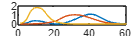

plot(xyz);


% xyz have smooth curves, while Ad does not. Green in Ad is more shifted to
% blue, while in xyz its shifted towards Red. xyz have larger "top" values

% 3.4

% Steps: 
% 1. Use linear regression to derivate an optimal conversion matrix A that
% maps calculated RBG values (D) to XYZ values (C) for the 20 color samples
% 2. Use A to estimate XYZ values from RGB values
% 3. Compute the color difference (ΔEab) between estimated and reference
% XYZ values, and report mean and maximum differences


% Compute optimal matrix A, Moore-Penrose pseudo-inverse
A = pinv(RGB_D65_Calibrated_Ad') * XYZ_D65_Ref'; % Represeting linear relationship between RGB and XYZ values

% Estimate XYZ vales using A
estimate = RGB_D65_Calibrated_Ad' * A;

% Compute color difference
dE2 = CalcED(XYZ_D65_Ref, estimate'); % Made own function for calculating

dE2_mean = mean(dE2)

dE2_mean = 2.1977

dE2_max = max(dE2)

dE2_max = 5.8376


% Improvments from 3.3. Barly visable color shift.
% Maximum of 5.8 can be visable but alot better then 31.6 in 3.3

% 3.5

A_Matrix = Optimize_poly(RGB_D65_Calibrated_Ad, XYZ_D65_Ref);
estimate2 = Polynomial_regression(RGB_D65_Calibrated_Ad, A_Matrix)

estimate2 =    66.5096   27.8573    9.7750   16.6392   36.9511   32.1922   52.3149    7.0672   34.8667    4.3226   15.8613   20.8865   14.1754   19.8283   34.5017   13.8445   26.9130   21.3759   58.9062   36.5895
   67.2542   24.9010    9.9852   16.4765   49.0317   35.9394   57.5626    6.3649   37.3760    4.2559   11.2072   17.8821   11.9189   25.7486   36.1026   10.4850   35.0129   18.3282   67.5508   37.6216
   60.9787   28.5960   14.3552   20.9662   50.1102   40.5785    9.8074    6.3964    5.0991    4.3336   16.2770   10.9571   11.5759    7.7201   65.7413   17.6776   55.0127    6.9452   18.0166   37.6376



dE3 = CalcED(XYZ_D65_Ref, estimate2)

dE3 =     0.0337    2.3631    1.6165    1.1127    0.3276    1.0344    0.9939    0.2794    0.8178    1.5029    3.1053    1.4415    1.4043    0.9943    0.1533    0.8119    0.1666    0.9143    0.6314    0.7719



dE3_mean = mean(dE3)

dE3_mean = 1.0238

dE3_max = max(dE3)

dE3_max = 3.1053


% We get an lower mean, saying that the color shifts are smaller then
% before, also the max color shift is only 3.1, thats barly visable